# Getting 

## Introduction

tbd

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters



% mVARboptions
linsys_solving_method = 'mldivide';
% linsys_solving_method = 'lsqlin';

get_VAR_eqs_steps       = '1-step';
% get_VAR_eqs_steps       = '2-steps';

log_write = 1;
log_name  = 'my_log';
log_path  = 'Escritorio/';


Nf = 100;

CC = colororder;
color_input = [0 0 0];
color_case0 = 0.7*[1 1 1];
color_case1 = CC(1,:);
color_case2 = CC(2,:);
color_case3 = CC(3,:);
color_case4 = CC(4,:);
linewidth = 2;
font_size = 14;
figure_position = [0 0 1000 600];
figure_position_2 = [0 0 1000 1000];
M_max_plot = 30;

load dataset_01_AR gamma_AR S_AR

gamma_input = gamma_AR;
clear gamma_AR;

M = gamma_input.x_parameters.M;


gamma0 = initialise_gamma('M',M);



mVARboptions = initialise_mVARboptions();
mVARboptions = fun_append_mVARboptions(mVARboptions,...
                                       'linsys_solving_method',linsys_solving_method,...
                                       'get_VAR_eqs_steps',get_VAR_eqs_steps,...
                                       'log_write',log_write,...
                                       'log_name',log_name,...
                                       'log_path',log_path);



### Case 0: Yule-Walker equations

j_vector = [1 2 3];
l_vector = [1 2 3];

AR_case0 = initialise_AR('j_vector',j_vector);

AR_case0 = get_AR_gamma(gamma_input, AR_case0, l_vector, mVARboptions);

gamma_case0 = get_gamma_AR(AR_case0,gamma0);


fprintf('j_vector is [%d, %d, %d] \n', AR_case0.restricted_parameters.j_vector)

j_vector is [1, 2, 3] 


fprintf('a_vector is [%.2f, %.2f, %.2f] \n', AR_case0.restricted_parameters.a_vector)

a_vector is [1.22, -0.57, 0.10] 


fprintf('b is %.2f \n',AR_case0.restricted_parameters.b)

b is 0.51 


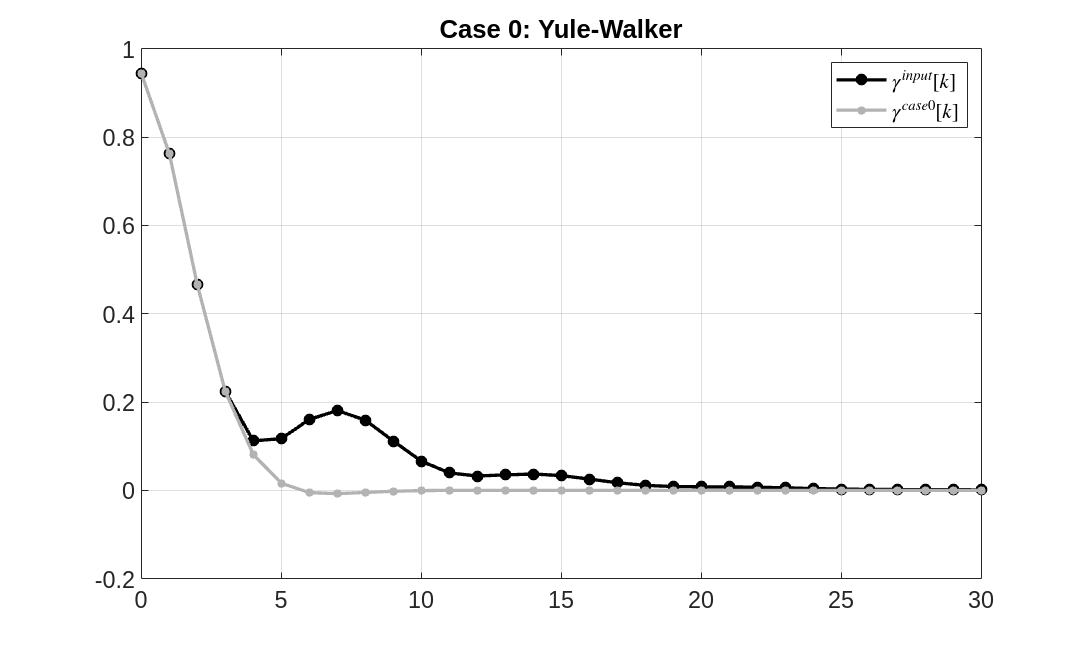




% Plot

figure

x = gamma_input.xlag_values;
y = gamma_input.y_values;
plot(x,y,'O-','color',color_input,'MarkerFaceColor',color_input,...
                                   'LineWidth',linewidth,...
                                   'markersize',5)
hold on
x = gamma_case0.xlag_values;
y = gamma_case0.y_values;
plot(x,y,'O-','color',color_case0,'MarkerFaceColor',color_case0,...
                                      'LineWidth',linewidth,...
                                      'markersize',3)

title('Case 0: Yule-Walker')
legend({'$\gamma^{input}[k]$','$\gamma^{case0}[k]$'},'interpreter','latex')
grid on
xlim([0 M_max_plot])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

### Case 1: unrestricted AR(3) with determined system of equations

j_vector = [1 2 3];
l_vector = [1 2 4];

AR_case1 = initialise_AR('j_vector',j_vector);

AR_case1 = get_AR_gamma(gamma_input, AR_case1, l_vector, mVARboptions);

gamma_case1 = get_gamma_AR(AR_case1,gamma0);


fprintf('j_vector is [%d, %d, %d] \n', AR_case1.restricted_parameters.j_vector)

j_vector is [1, 2, 3] 


fprintf('a_vector is [%.2f, %.2f, %.2f] \n', AR_case1.restricted_parameters.a_vector)

a_vector is [1.27, -0.69, 0.20] 


fprintf('b is %.2f \n',AR_case1.restricted_parameters.b)

b is 0.50 


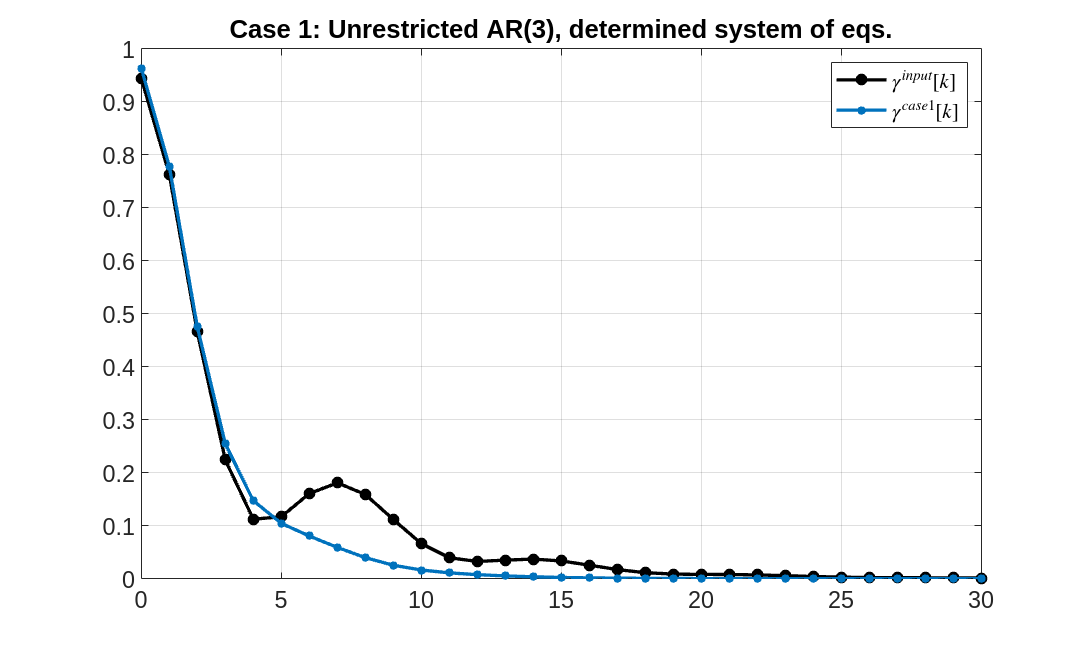




% Plot

figure

x = gamma_input.xlag_values;
y = gamma_input.y_values;
plot(x,y,'O-','color',color_input,'MarkerFaceColor',color_input,...
                                   'LineWidth',linewidth,...
                                   'markersize',5)
hold on
x = gamma_case1.xlag_values;
y = gamma_case1.y_values;
plot(x,y,'O-','color',color_case1,'MarkerFaceColor',color_case1,...
                                      'LineWidth',linewidth,...
                                      'markersize',3)

title('Case 1: Unrestricted AR(3), determined system of eqs.')
legend({'$\gamma^{input}[k]$','$\gamma^{case1}[k]$'},'interpreter','latex')
grid on
xlim([0 M_max_plot])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

### Case 2: unrestricted AR(3) with overdetermined system of equations


j_vector = [1 2 3];
l_vector = 1:20;

AR_case2 = initialise_AR('j_vector',j_vector);

AR_case2 = get_AR_gamma(gamma_input, AR_case2, l_vector, mVARboptions);

gamma_case2 = get_gamma_AR(AR_case2,gamma0);


fprintf('j_vector is [%d, %d, %d] \n', AR_case2.restricted_parameters.j_vector)

j_vector is [1, 2, 3] 


fprintf('a_vector is [%.2f, %.2f, %.2f] \n', AR_case2.restricted_parameters.a_vector)

a_vector is [1.47, -1.00, 0.34] 


fprintf('b is %.2f \n',AR_case2.restricted_parameters.b)

b is 0.46 


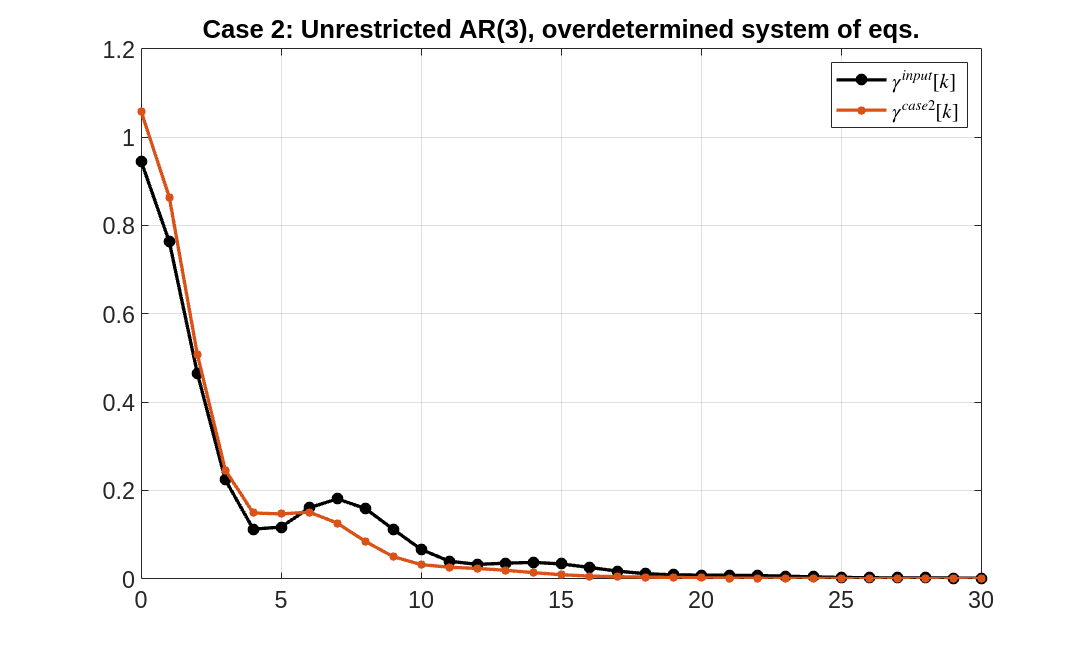



% Plot

figure

x = gamma_input.xlag_values;
y = gamma_input.y_values;
plot(x,y,'O-','color',color_input,'MarkerFaceColor',color_input,...
                                   'LineWidth',linewidth,...
                                   'markersize',5)
hold on
x = gamma_case2.xlag_values;
y = gamma_case2.y_values;
plot(x,y,'O-','color',color_case2,'MarkerFaceColor',color_case2,...
                                      'LineWidth',linewidth,...
                                      'markersize',3)

title('Case 2: Unrestricted AR(3), overdetermined system of eqs.')
legend({'$\gamma^{input}[k]$','$\gamma^{case2}[k]$'},'interpreter','latex')
grid on
xlim([0 M_max_plot])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

### Case 3: Restricted AR(3) with determined system of equations

j_vector = [1 2 4];
l_vector = [1 2 4];

AR_case3 = initialise_AR('j_vector',j_vector);

AR_case3 = get_AR_gamma(gamma_input, AR_case3, l_vector, mVARboptions);

gamma_case3 = get_gamma_AR(AR_case3,gamma0);


fprintf('j_vector is [%d, %d, %d] \n', AR_case3.restricted_parameters.j_vector)

j_vector is [1, 2, 4] 


fprintf('a_vector is [%.2f, %.2f, %.2f] \n', AR_case3.restricted_parameters.a_vector)

a_vector is [1.22, -0.54, 0.10] 


fprintf('b is %.2f \n',AR_case3.restricted_parameters.b)

b is 0.50 


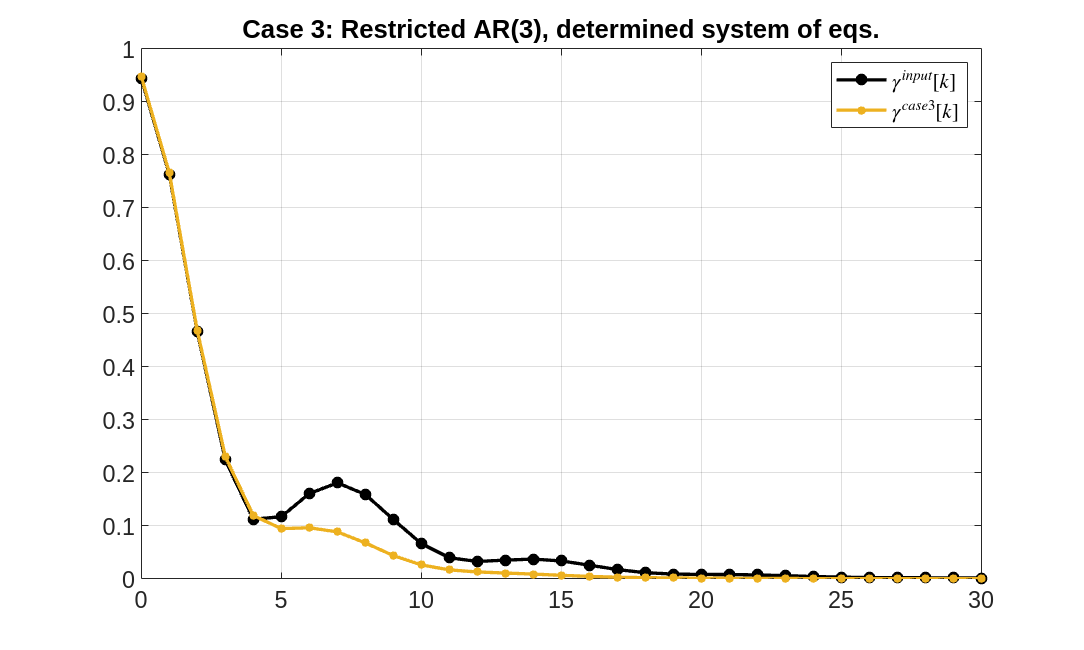



% Plot

figure

x = gamma_input.xlag_values;
y = gamma_input.y_values;
plot(x,y,'O-','color',color_input,'MarkerFaceColor',color_input,...
                                   'LineWidth',linewidth,...
                                   'markersize',5)
hold on
x = gamma_case3.xlag_values;
y = gamma_case3.y_values;
plot(x,y,'O-','color',color_case3,'MarkerFaceColor',color_case3,...
                                      'LineWidth',linewidth,...
                                      'markersize',3)

title('Case 3: Restricted AR(3), determined system of eqs.')
legend({'$\gamma^{input}[k]$','$\gamma^{case3}[k]$'},'interpreter','latex')
grid on
xlim([0 M_max_plot])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

### Case 4: Restricted AR(3) with overdetermined system of equations

j_vector = [1 2 4];
l_vector = 1:20;

AR_case4 = initialise_AR('j_vector',j_vector);

AR_case4 = get_AR_gamma(gamma_input, AR_case4, l_vector, mVARboptions);

gamma_case4 = get_gamma_AR(AR_case4,gamma0);


fprintf('j_vector is [%d, %d, %d] \n', AR_case4.restricted_parameters.j_vector)

j_vector is [1, 2, 4] 


fprintf('a_vector is [%.2f, %.2f, %.2f] \n', AR_case4.restricted_parameters.a_vector)

a_vector is [1.32, -0.66, 0.15] 


fprintf('b is %.2f \n',AR_case4.restricted_parameters.b)

b is 0.48 


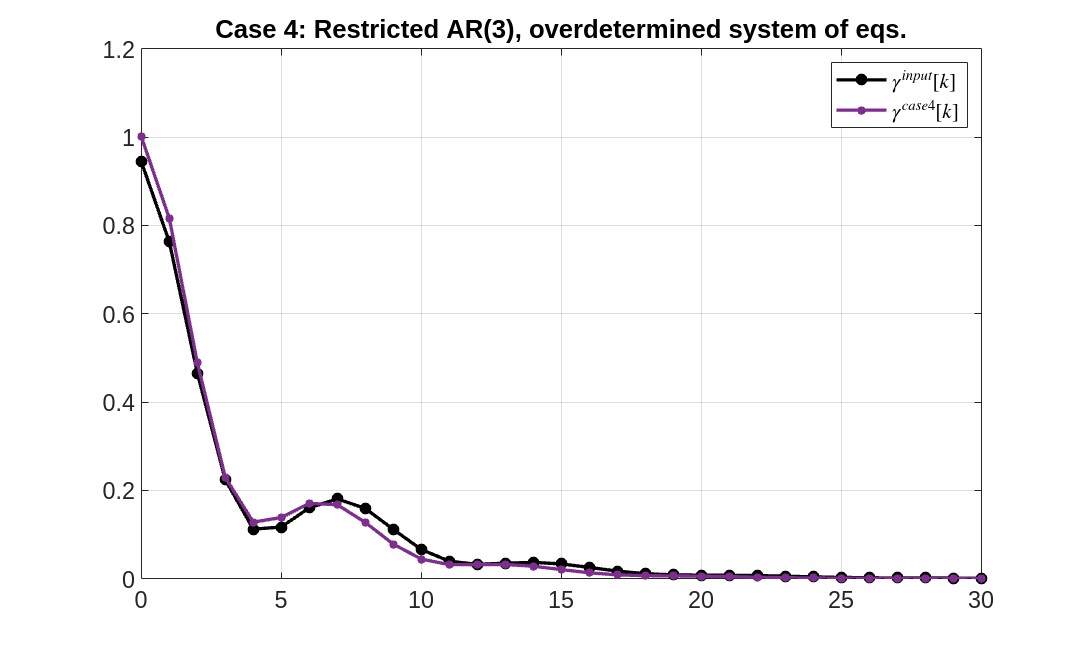


% Plot

figure

x = gamma_input.xlag_values;
y = gamma_input.y_values;
plot(x,y,'O-','color',color_input,'MarkerFaceColor',color_input,...
                                   'LineWidth',linewidth,...
                                   'markersize',5)
hold on
x = gamma_case4.xlag_values;
y = gamma_case4.y_values;
plot(x,y,'O-','color',color_case4,'MarkerFaceColor',color_case4,...
                                      'LineWidth',linewidth,...
                                      'markersize',3)

title('Case 4: Restricted AR(3), overdetermined system of eqs.')
legend({'$\gamma^{input}[k]$','$\gamma^{case4}[k]$'},'interpreter','latex')
grid on
xlim([0 M_max_plot])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

### Comparison of PSDs

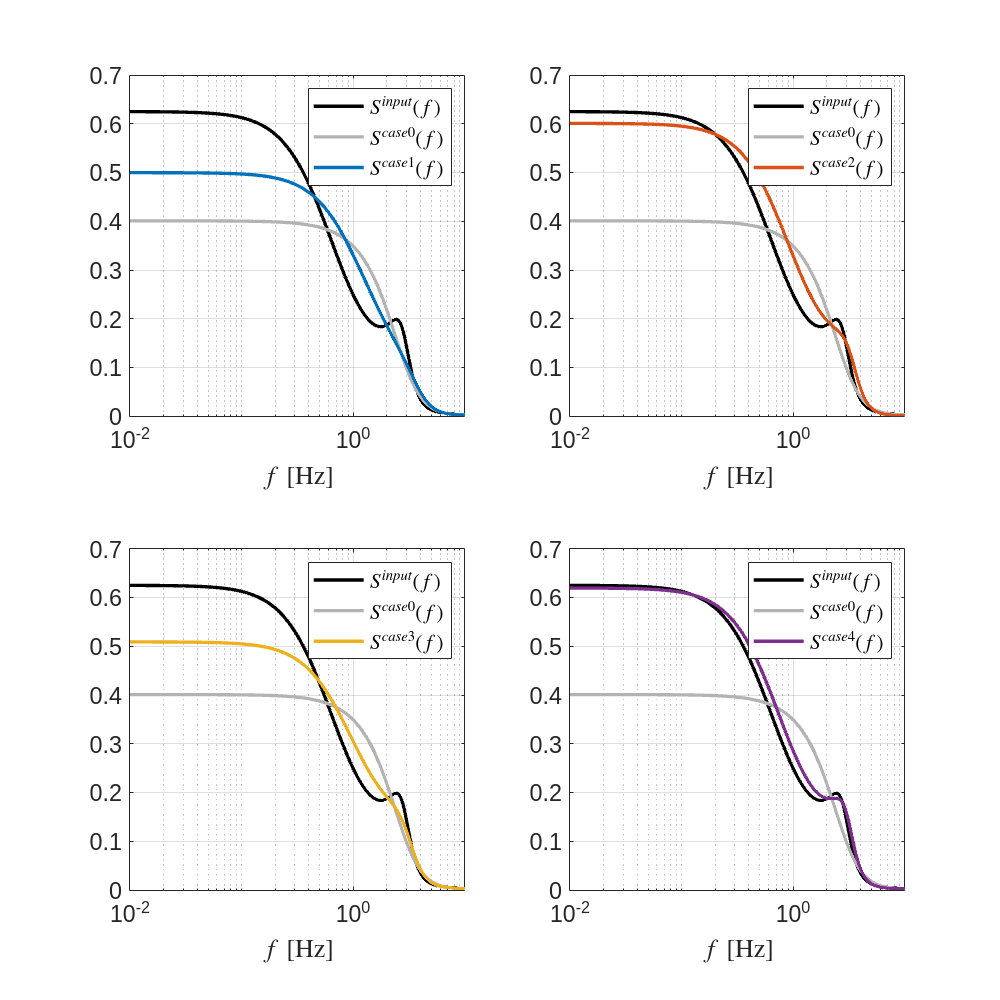

S0 = initialise_S('ind_var',S_AR.ind_var,...
                  'x_values',S_AR.x_values,...
                  'x_max',S_AR.x_parameters.x_max);

S_case0 = get_S_AR(AR_case0, S0);
S_case1 = get_S_AR(AR_case1, S0);
S_case2 = get_S_AR(AR_case2, S0);
S_case3 = get_S_AR(AR_case3, S0);
S_case4 = get_S_AR(AR_case4, S0);


figure

subplot(2,2,1)

x = S_AR.x_values;
y = S_AR.y_values;
plot(x,y,'-','color',color_input,'LineWidth',linewidth)
hold on
y = S_case0.y_values;
plot(x,y,'-','color',color_case0,'LineWidth',linewidth)
y = S_case1.y_values;
plot(x,y,'-','color',color_case1,'LineWidth',linewidth)
xlabel('$f$ [Hz]', 'Interpreter','latex')
grid on
legend({'$S^{input}(f)$','$S^{case0}(f)$','$S^{case1}(f)$'},...
        'Interpreter','latex')
set(gca,'fontsize',font_size)
set(gca,'xscale','log')


subplot(2,2,2)

x = S_AR.x_values;
y = S_AR.y_values;
plot(x,y,'-','color',color_input,'LineWidth',linewidth)
hold on
y = S_case0.y_values;
plot(x,y,'-','color',color_case0,'LineWidth',linewidth)
y = S_case2.y_values;
plot(x,y,'-','color',color_case2,'LineWidth',linewidth)
xlabel('$f$ [Hz]', 'Interpreter','latex')
grid on
legend({'$S^{input}(f)$','$S^{case0}(f)$','$S^{case2}(f)$'},...
        'Interpreter','latex')
set(gca,'fontsize',font_size)
set(gca,'xscale','log')


subplot(2,2,3)

x = S_AR.x_values;
y = S_AR.y_values;
plot(x,y,'-','color',color_input,'LineWidth',linewidth)
hold on
y = S_case0.y_values;
plot(x,y,'-','color',color_case0,'LineWidth',linewidth)
y = S_case3.y_values;
plot(x,y,'-','color',color_case3,'LineWidth',linewidth)
xlabel('$f$ [Hz]', 'Interpreter','latex')
grid on
legend({'$S^{input}(f)$','$S^{case0}(f)$','$S^{case3}(f)$'},...
        'Interpreter','latex')
set(gca,'fontsize',font_size)
set(gca,'xscale','log')


subplot(2,2,4)

x = S_AR.x_values;
y = S_AR.y_values;
plot(x,y,'-','color',color_input,'LineWidth',linewidth)
hold on
y = S_case0.y_values;
plot(x,y,'-','color',color_case0,'LineWidth',linewidth)
y = S_case4.y_values;
plot(x,y,'-','color',color_case4,'LineWidth',linewidth)
xlabel('$f$ [Hz]', 'Interpreter','latex')
grid on
legend({'$S^{input}(f)$','$S^{case0}(f)$','$S^{case4}(f)$'},...
        'Interpreter','latex')
set(gca,'fontsize',font_size)
set(gca,'xscale','log')


set(gcf,'position',figure_position_2)

## Remarks

- tbd